% 基础参数的设置
prompt = {'设定录制时长（秒）：','设定采样频率（HZ）：'};
dlg_title = '设置录音参数';
num_lin = 1;
def_t_f = {'5','16000'};
record_par = inputdlg(prompt,dlg_title,num_lin,def_t_f);

if isempty(record_par)
    error('用户取消了输入');
end

% 录音前的准备工作
record_t = str2double(record_par{1});
Fs = str2double(record_par{2});

% 创建音频录制对象
record_speech = audiorecorder(Fs, 16, 2); % 16位深度，2个通道

% 提示录音开始
disp('请开始录音...');

请开始录音...


h = waitbar(0,'录音中...');

% 正式开始录制
recordblocking(record_speech, record_t);
close(h);

disp('录音结束');

录音结束



% 获取音频数据
speech_data = getaudiodata(record_speech);

% 因为声音太小，所以我尝试添加一个 增益因子，来扩大声音
gain = 10; % 通过几次尝试发现 10还是比较合适的
amplified_speech_data = speech_data * gain;

% 播放录音
disp('正在播放录音...')

正在播放录音...


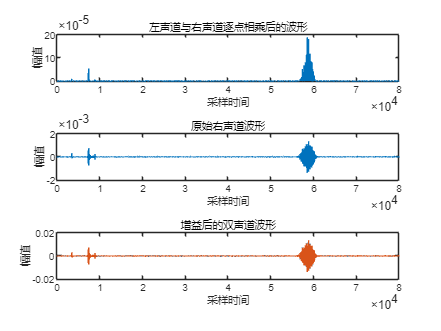

sound(amplified_speech_data, Fs);

% 绘制波形
figure;
subplot(3,1,1);
plot(speech_data(:,1));
xlabel('采样时间');
ylabel('幅值');
title('原始左声道波形');

subplot(3,1,2);
plot(speech_data(:,2));
xlabel('采样时间');
ylabel('幅值');
title('原始右声道波形');

subplot(3,1,3);
plot(amplified_speech_data);
xlabel('采样时间');
ylabel('幅值');
title('增益后的双声道波形');

% % 调用函数进行运算
[left_sum, left_diff, left_product] = process_dual_channel(amplified_speech_data(:,1), amplified_speech_data(:,2));
% 
% % 绘制处理后的波形
% figure;
% subplot(3,1,1);
% plot(left_sum);
% xlabel('采样时间');
% ylabel('幅值');
% title('左声道与右声道相加后的波形');
% 
% subplot(3,1,2);
% plot(left_diff);
% xlabel('采样时间');
% ylabel('幅值');
% title('左声道与右声道相减后的波形');
% 
figure;
subplot(3,1,1);
plot(left_product);
xlabel('采样时间');
ylabel('幅值');
title('左声道与右声道逐点相乘后的波形');

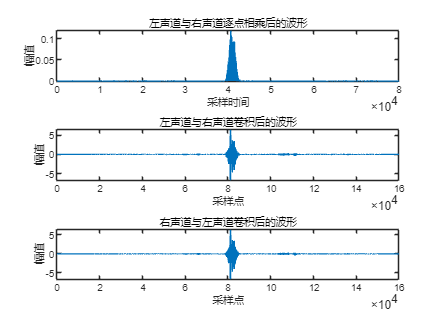

% 调用函数进行卷积运算
[conv_lr, conv_rl] = convolve_dual_channel(amplified_speech_data(:,1), amplified_speech_data(:,2));

% 绘制卷积后的波形

subplot(3,1,2);
plot(conv_lr);
xlabel('采样点');
ylabel('幅值');
title('左声道与右声道卷积后的波形');

subplot(3,1,3);
plot(conv_rl);
xlabel('采样点');
ylabel('幅值');
title('右声道与左声道卷积后的波形');